M=1000;
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;

## A_f and B_f matrices

A_f =[0 1 0 0 0 0;0 0 (-m1*g)/M 0 (-m2*g)/M 0;0 0 0 1 0 0;0 0 -(g/l1)*((m1+M)/M) 0 (-m2*g)/M*l1 0;0 0 0 0 0 1;0 0 (-m1*g)/M*l2 0 -(g/l2)*((m2+M)/M) 0]

A_f =          0    1.0000         0         0         0         0
         0         0   -0.9810         0   -0.9810         0
         0         0         0    1.0000         0         0
         0         0   -0.5396         0  -19.6200         0
         0         0         0         0         0    1.0000
         0         0   -9.8100         0   -1.0791         0


B_f =[0;1/M;0;1/(M*l1);0;1/(M*l2)]

B_f = 	1.0e+-3 *

         0
    1.0000
         0
    0.0500
         0
    0.1000


eigs(A_f)

ans =   -0.0000 + 3.8322i
  -0.0000 - 3.8322i
  -3.6148 + 0.0000i
   3.6148 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


C = [1 0 0 0 0 0;0 0 1 0 0 0;0 0 0 0 1 0;]

C =      1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     1     0


D = [0;0;0]

D =      0
     0
     0



plant = ss(A_f,B_f,C,D);
Plant_poles = pole(plant);

## Controllability Matrix and rank condition

Co = ctrb(plant);
Ob = obsv(plant);
rank_Co = rank(Co);
eig_Co = eigs(Co);
rank_Ob = rank(Ob);
%eig_Ob = eigs(Ob);

## Initial conditions

I = [0;1;1;0;1;0];

## Luenberger Observer Design 

Observerbility check for x(t),theta_1(t), and theta_2(t)

C_Lo = ctrb(A_f',C')

C_Lo =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0   -0.9810   -0.5396   -9.8100         0         0         0   10.1529  192.7633   15.8790         0         0         0
         0         0         0         0    1.0000         0         0         0         0   -0.9810   -0.5396   -9.8100         0         0         0   10.1529  192.7633   15.8790
         0         0    1.0000         0         0         0   -0.9810  -19.6200   -1.0791         0         0         0   20.3058   31.7579  193.6367         0         0         0
         0         0         0         0         0    1.0000         0         0        

rank(C_Lo)

ans = 6

Ob_Lo = obsv(A_f,C)

Ob_Lo =     1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0         0    1.0000         0
         0    1.0000         0         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000
         0         0   -0.9810         0   -0.9810         0
         0         0   -0.5396         0  -19.6200         0
         0         0   -9.8100         0   -1.0791         0
         0         0         0   -0.9810         0   -0.9810


rank(Ob_Lo)

ans = 6


pole(Plant_LQR)

ans =  -14.5859 +13.6057i
 -14.5859 -13.6057i
  -2.1921 + 3.6421i
  -2.1921 - 3.6421i
  -5.5397 + 0.0000i
  -3.6311 + 0.0000i


Poles_L_Obs = [-28;-30;-10;-6;-2;-4]

Poles_L_Obs =    -28
   -30
   -10
    -6
    -2
    -4


L = place(A_f',C',Poles_L_Obs)'

L =    24.6012    3.0047   10.7179
   87.8210    8.7493   59.2856
    0.8441   31.8371   -2.7304
   -7.4693  119.8831  -51.1957
   11.4406   -5.0483   23.5617
   69.4268  -57.9228   96.6033



Luen_SYS = ss(A_f-L*C,B_f,C,D)


Luen_SYS =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1    -24.6        1   -3.005        0   -10.72        0
   x2   -87.82        0    -9.73        0   -60.27        0
   x3  -0.8441        0   -31.84        1     2.73        0
   x4    7.469        0   -120.4        0    31.58        0
   x5   -11.44        0    5.048        0   -23.56        1
   x6   -69.43        0    48.11        0   -97.68        0
 
  B = 
           u1
   x1       0
   x2   0.001
   x3       0
   x4   5e-05
   x5       0
   x6  0.0001
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   0   1   0   0   0
   y3   0   0   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



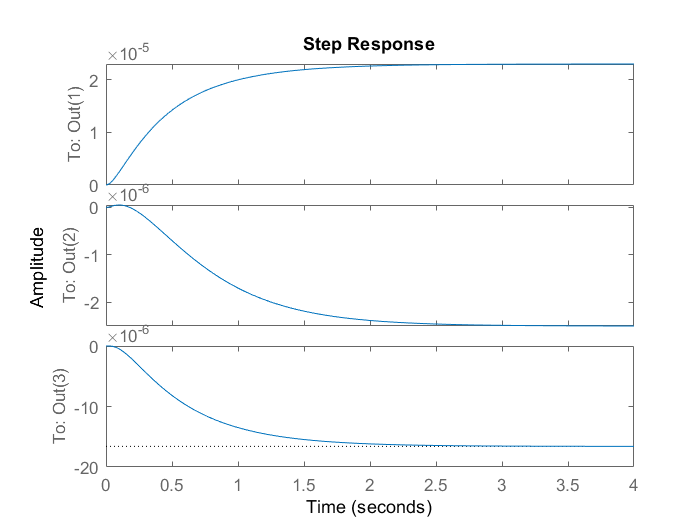

step(Luen_SYS)


eigs(A_f' - C'*L')

ans =   -30.0000
  -28.0000
  -10.0000
   -6.0000
   -4.0000
   -2.0000
